clear;

## Feeding model for Holstein heifers.


$$\mathrm{DMI}=15\ldotp 36\cdot \left(1-e^{-0\ldotp 0022\cdot \mathrm{BW}} \right)$$
  

  Get the feeding model data. This is the Body Weight Growth according to

% Get feeding model data from excel file
data = readmatrix('feed-model-data.xlsx', 'Sheet',"raw");
bw_model_data = data(:,1);
dmi_model_data = data(:,2);
days  = size(data,1);
daypoints = 1:days;

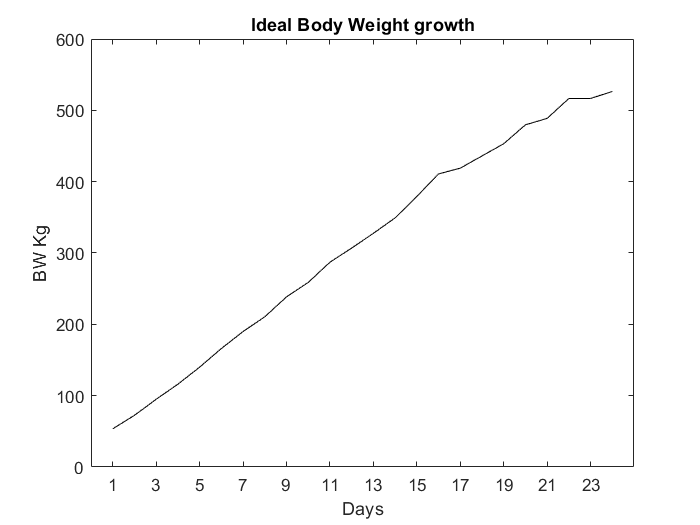

% Plot ideal body weight growth
plot(daypoints,bw_model_data,'-k')
title('Ideal Body Weight growth');
ylim([0,600]);
ylabel('BW Kg')
xlabel('Days')
xticks(1:2:days)

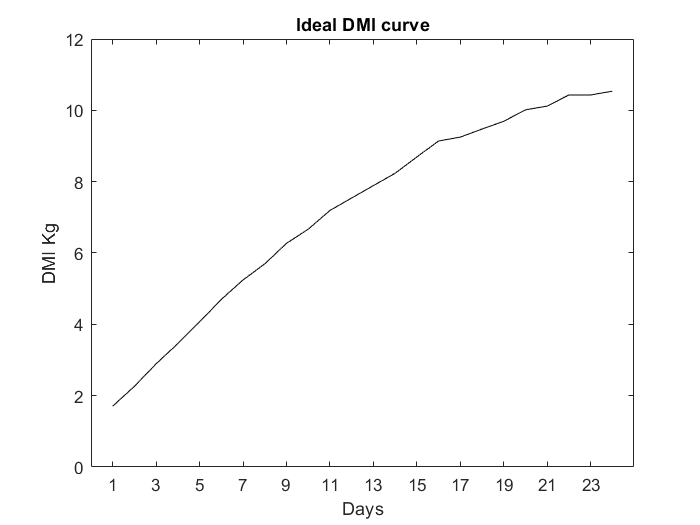


% Plot ideal DMI
plot(daypoints,dmi_model_data,'-k')
title('Ideal DMI curve');
ylim([0,12]);
ylabel('DMI Kg')
xlabel('Days')
xticks(1:2:days)

## Generate sample body weight curves

% Generate sample body weight curves
points = [
    50 160 320 420;    
    50 200 380 500;
    55 260 450 550;
    55 290 500 580
    ];
[rows, cols] = size(points);

x = 1:days;
bw_sample_data = zeros(days,rows);
for i=1:rows
    data = nan(days,1);
    data(1) = points(i,1);
    data(9) = points(i,2);
    data(17) = points(i,3);
    data(end) = points(i,4);
    data = fillmissing(data,'spline','SamplePoints',x);
    bw_sample_data(:,i) = data;
end

## Compare actual and ideal BW curves

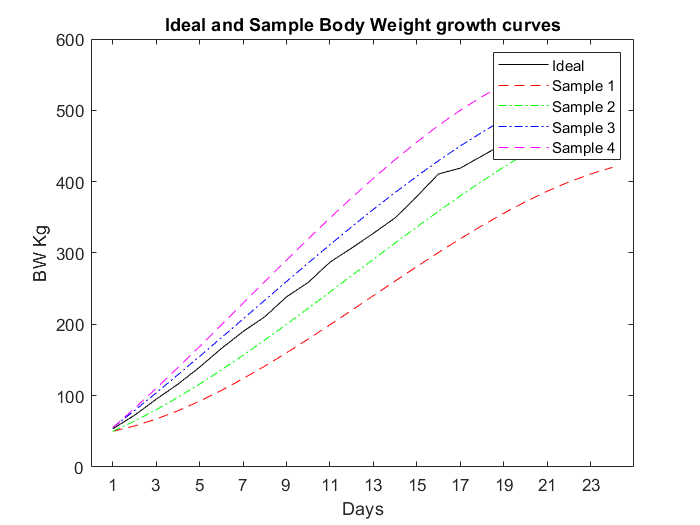

% Plot generated curves with ideal curve
plot(daypoints,bw_model_data,'-k')
hold on 
plot(daypoints,bw_sample_data(:,1),'--r')
plot(daypoints,bw_sample_data(:,2),'-.g')
plot(daypoints,bw_sample_data(:,3),'-.b')
plot(daypoints,bw_sample_data(:,4),'--m')
hold off
title("Ideal and Sample Body Weight growth curves")
xticks(1:2:days)
ylabel("BW Kg")
xlabel("Days")
legend('Ideal','Sample 1','Sample 2','Sample 3','Sample 4');

a = 15.36;
b = 0.0022;
dmi_sample_data = zeros(days,rows);
for i=1:rows
    dmi_sample_data(:,i) = dmimodel(a,b, bw_sample_data(:,i));
end

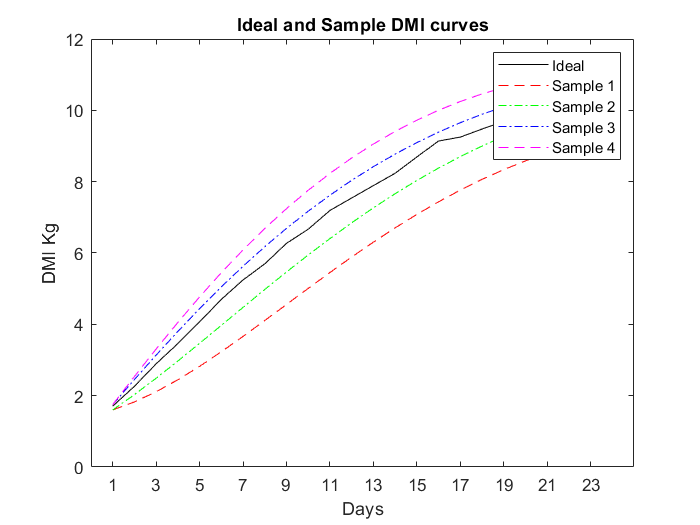

% Plot generated curves with ideal curve
plot(daypoints,dmi_model_data,'-k')
hold on 
plot(daypoints,dmi_sample_data(:,1),'--r')
plot(daypoints,dmi_sample_data(:,2),'-.g')
plot(daypoints,dmi_sample_data(:,3),'-.b')
plot(daypoints,dmi_sample_data(:,4),'--m')
hold off
title("Ideal and Sample DMI curves")
xticks(1:2:days)
ylabel("DMI Kg")
xlabel("Days")
legend('Ideal','Sample 1','Sample 2','Sample 3','Sample 4');

## Decide if curve is similar using Root Mean Square Distance and Correlation coeficiant

base_distance_err = 35;
base_cor_err = 0.96;
daypoint = 10;
for i=1:rows
    err = sqrt(mean((bw_model_data(1:daypoint,:)-bw_sample_data(1:daypoint,i)).^2));
    cor = corr2(bw_model_data(1:daypoint,:),bw_sample_data(1:daypoint,i));
   
    fprintf("Distance error for curve %d is %.2f", i, err);
    fprintf("Correlation coeficiant for curve %d is %.4f", i, cor);
    if err < base_distance_err && cor > base_cor_err
        fprintf('OK! Curve is similar with model')
    else
        fprintf("Warning! Curve is not similar with model")
    end
    disp('..')
end

Distance error for curve 1 is 54.53

Correlation coeficiant for curve 1 is 0.9940

Warning! Curve is not similar with model

..


Distance error for curve 2 is 26.57

Correlation coeficiant for curve 2 is 0.9987

OK! Curve is similar with model

..


Distance error for curve 3 is 16.76

Correlation coeficiant for curve 3 is 0.9997

OK! Curve is similar with model

..


Distance error for curve 4 is 36.30

Correlation coeficiant for curve 4 is 0.9998

Warning! Curve is not similar with model

..


## Explore the impact for a, and b parameters in feeding model equation

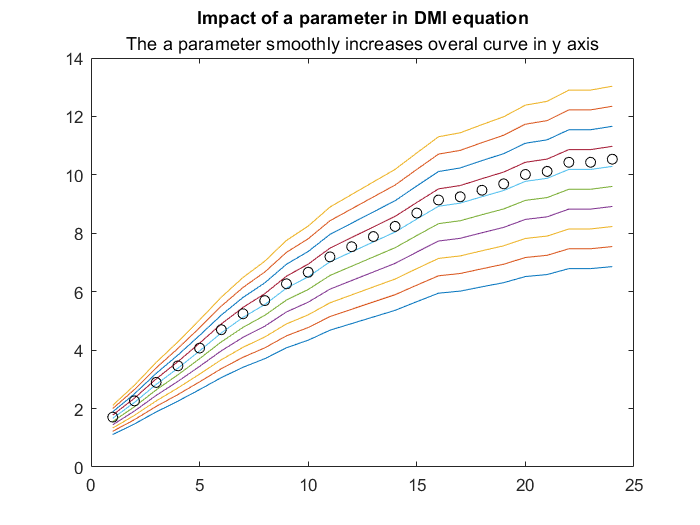

% explore dmi model parameters
% Dmi equation parameters
a = 15.36;
b = 0.0022;
as = [10:1:19];
bs = linspace(0.0005,0.0090,10);

for a = as
   
    dmi = dmimodel(a,b,bw_model_data);
    plot(dmi);
    hold on;
end
plot(dmi_model_data,'ok');
title('Impact of a parameter in DMI equation')
subtitle('The a parameter smoothly increases overal curve in y axis')
hold off;

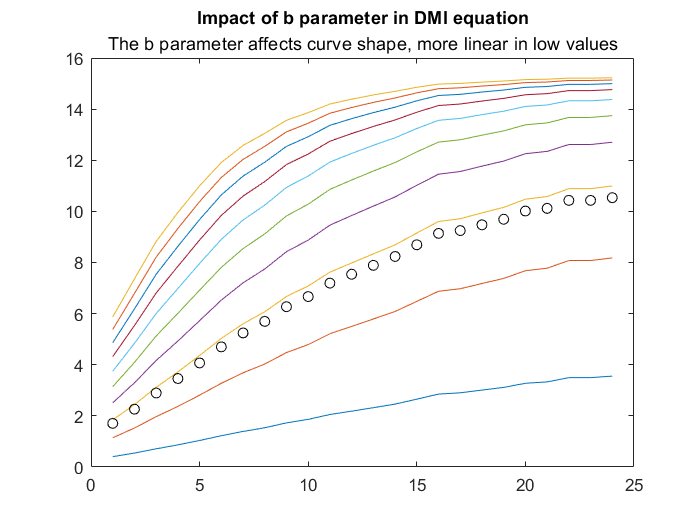


a = 15.36;
for b = bs
   
    dmi = dmimodel(a,b,bw_model_data);
    plot(dmi);
    hold on;
end
plot(dmi_model_data,'ok');
title('Impact of b parameter in DMI equation')
subtitle('The b parameter affects curve shape, more linear in low values')
hold off;

## Example of a parameter correction

Feed sample BW data until day 12

If curve is not similar calculate new a parameter

new_a = a * (1 + err_percent )

Where err_percent  = rmse_error / BW ideal

past_days = 12

Mean square distance of curve from ideal = 61.27

err_percent = 0.1996

Error percent of distance to ideal curve = 19.96 %

New a parameter for DMI model = a * error percent =  18.43

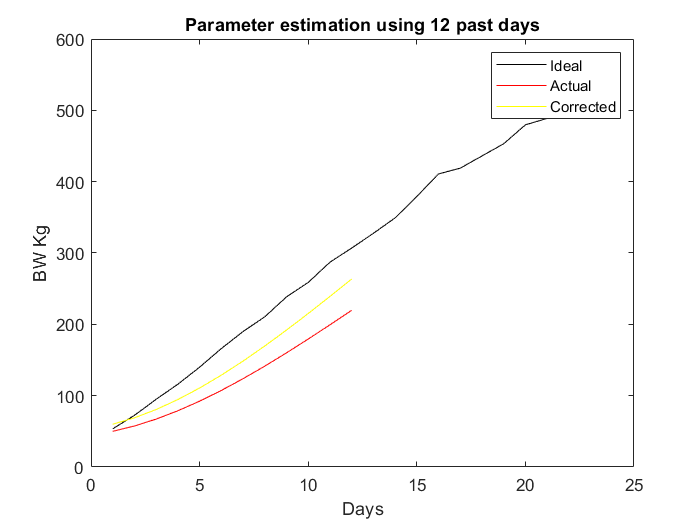

past_days = 8

Mean square distance of curve from ideal = 73.01

err_percent = 0.2379

Error percent of distance to ideal curve = 23.79 %

New a parameter for DMI model = a * error percent =  19.01

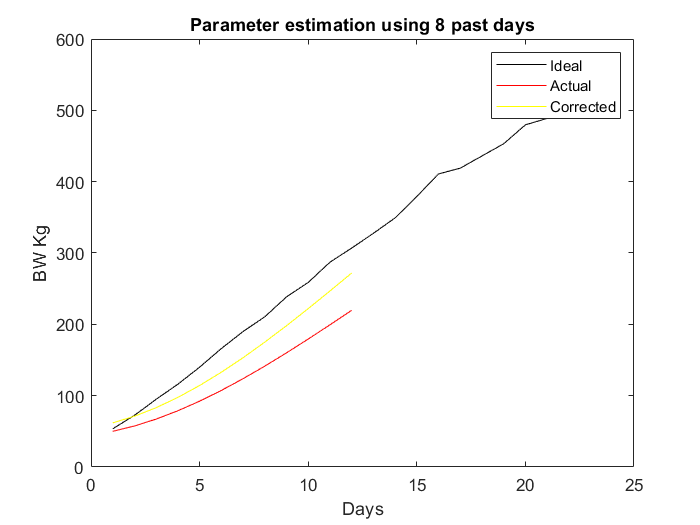

past_days = 5

Mean square distance of curve from ideal = 80.70

err_percent = 0.2629

Error percent of distance to ideal curve = 26.29 %

New a parameter for DMI model = a * error percent =  19.40

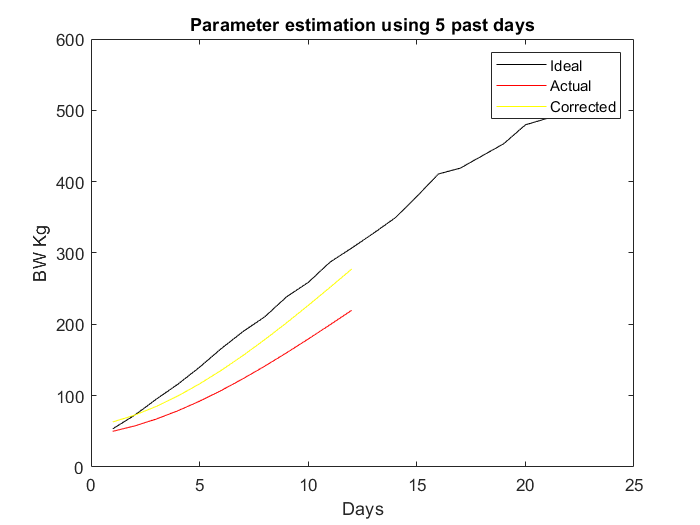

for k = [1 5 8]
    figure
    current_day = 12;
    previous_day = k;
    sample_data = bw_sample_data(1:current_day,1);
    plot(bw_model_data,'-k');
    hold on
    plot(sample_data,'-r');
    ylabel("BW Kg");
    xlabel("Days");
    ylim([0 600]);
    past_days = current_day - previous_day + 1
    formated_title = sprintf('Parameter estimation using %d past days', past_days);
    title(formated_title);
    
    
    err = sqrt(mean((bw_model_data(previous_day:current_day,:)-sample_data(previous_day:current_day)).^2));
    bw_model_data(current_day);
    fprintf("Mean square distance of curve from ideal = %.2f", err)
    err_percent = err / bw_model_data(current_day)
    fprintf("Error percent of distance to ideal curve = %.2f %%", err_percent * 100)
    new_a = a * (1 + err_percent );
    fprintf("New a parameter for DMI model = a * error percent =  %.2f", new_a)
    
    plot(sample_data .* (1 + err_percent ) ,'-y');
    legend('Ideal', 'Actual', 'Corrected')
    hold off
    
end

## Functions for the DMI equation and the inverse BW calculation

function dmi = dmimodel(a,b,bw)
    dmi = a * (1 - exp(-b * bw));
end
function bw = bwmodel(a,b,dmi)
    bw = log((a-dmi)/a) * (-1/b);
end